clear
format shortG
warning off;
SetRNG(111);
% generate input data
%hierarchy 1 and 2 generation
k = 4;
dim = 100;
mu_range = [-1000 1000];
sigma = 100;
split_num = 2;
[center1,mu_mat] = subcluster_centroid(k,dim,split_num,mu_range,sigma); 
means = [];


%hierarchy 3 generation
center2 = [];  
for i = 1:size(center1,1)
    r = normrnd(0,20,[3,100])+center1(i,:);
    center2 = [center2;r];
end
center = center2;

% data generation with the given centroids
dim = 100;
num = 100;
sigma = 5;
[inputs,c] = subcluster_simulate(center,dim,num,sigma);
assign_id1 = repelem([1:4],600)';
assign_id2 = repelem([1:8],300)';
assign_id3 = repelem([1:24],100)';


data = inputs';

c2c_dist_layer1 = norm(mu_mat(2,:)'-mu_mat(1,:)',2);
c2c_dist_layer2 = norm(center1(2,:)'-center1(1,:)',2);
c2c_dist_layer3 = norm(center2(2,:)'-center2(1,:)',2);
tree1 = linkage(data','average','cosine');

%MNIST data

load ('mnist.mat')
colormap(gray(256))
images = rescale(test.images(:,:,:),0,255);
data = reshape(images,784,10000);
MNIST_inputs = data';
tree2 = linkage(MNIST_inputs,'average','cosine');

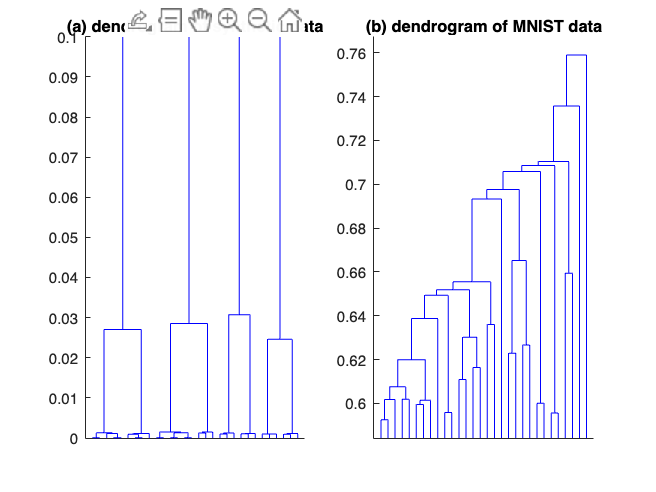

figure;
subplot(1,2,1)
dendrogram(tree1)
ylim([0 0.1])
set(gca, 'XTick', []);
title("(a) dendrogram of synthetic data")
subplot(1,2,2)
dendrogram(tree2)
title("(b) dendrogram of MNIST data")
set(gca, 'XTick', []);